clear all
close all

## Model Parameters

Define model parameters for simple pendulum system

m = 1;                  % mass at end of pendulum
l = 1;                  % length of pendulum
a = 0.5;                % height of attachment of spring/damper
k = 80;                 % spring constant
d = 10;                 % damping constant
I = m*l^2;              % inertia
g = 10;                 % acceleration of gravity

## Simulation parameters

Tend = 5;               % simulation time length
x0 = [30/180*pi, 0];    % initial condition (try e.g. 30, 55, 60, 65)
xl = [0/180*pi, 0];     % linearization point
Ts = 0.1;               % sampling time for discretization

## Exercice 1: Nonlinear Simulation of the System

We implement the differential equation of the pendulum as an anonymous function

$\dot{x} = f(x) = \pmatrix{ x_2 \cr  \frac{g}{l} \sin (x_1) - \frac{a^2}{ml^2} \cos(x_1) (k \sin(x_1) + d \cos(x_1)x_2)}$.

fx = @(t,x) [ x(2);
            g/l*sin(x(1)) - a^2/(m*l^2)*cos(x(1))*(k*sin(x(1)) + d*cos(x(1))*x(2))];

And we simulate the system using a  suitable ODE solver and plot the results

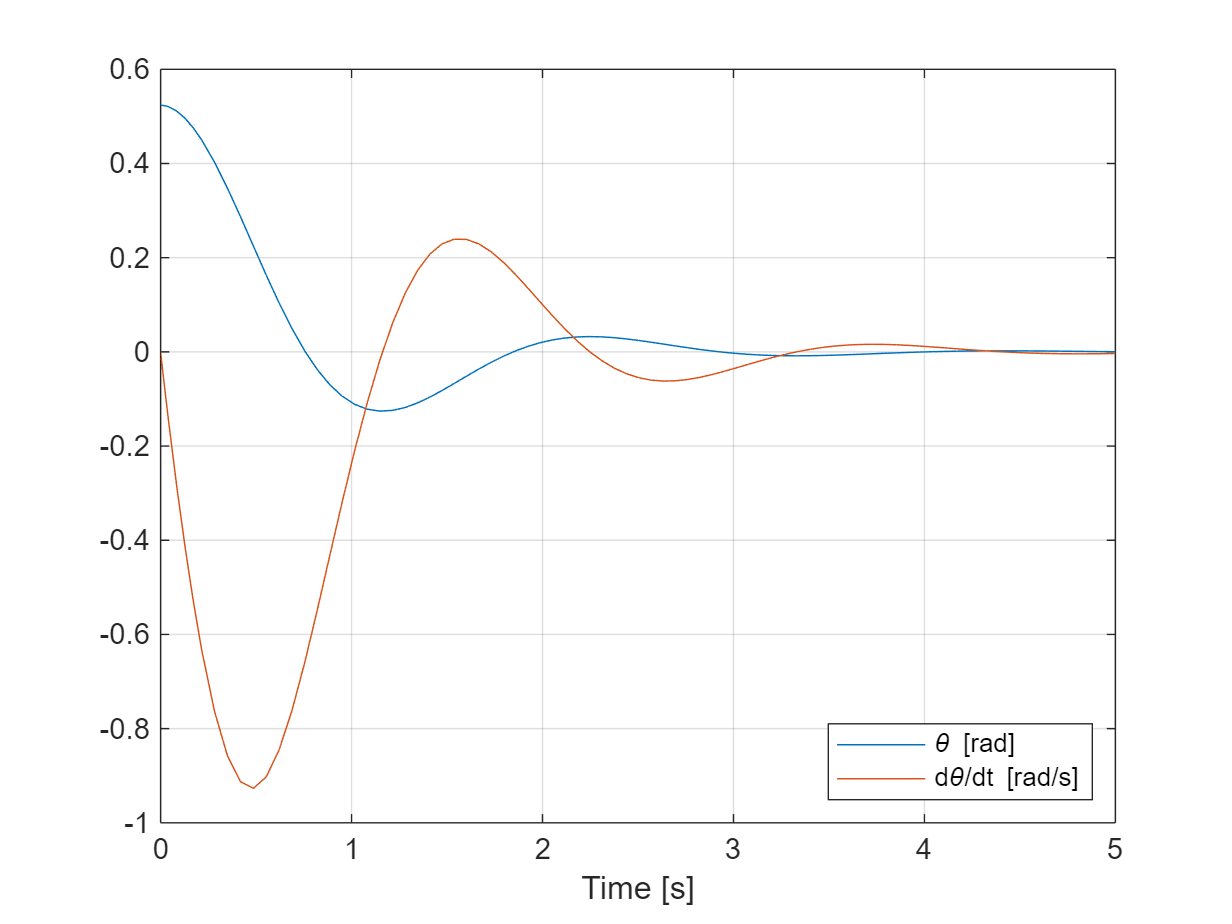

[tSimNL,xSimNL] = ode45(fx,[0, Tend],x0);

figure(1)
plot(tSimNL,xSimNL)
xlabel('Time [s]');
legend('\theta [rad]','d\theta/dt [rad/s]','Location','southeast')
grid on

## Exercise 2: Linearization

Linearzation yields approximate dynamics


$$\dot{x} \approx f(\hat{x}) + \left.\frac{\partial f(x)}{\partial x}\right|_{x=\hat{x}} (x - \hat{x})$$


where for equilibrium points are characterized by $f(\hat{x}) = 0$.

Linearizing $f(x)$ (by hand) gives


$$\left.\frac{\partial f(x)}{\partial x}\right|_{x=\hat{x}} = \pmatrix{0 & 1 \cr \frac{g}{l}\cos(\hat{x}_1) - \frac{a^2}{ml^2} \left( k(\cos^2(\hat{x}_1) - \sin^2(\hat{x}_1)) - 2 d\hat{x}_2 \cos(\hat{x}_1) \sin(\hat{x}_1)\right) & -\frac{a^2}{ml^2} d \cos^2(\hat{x}_1)}$$


fAc = @(xl)    [   0 ,   1;
                    g/l*cos(xl(1))-a^2/(m*l^2)*(...
                        k*(cos(xl(1))^2 - sin(xl(1))^2) ...
                        -2*d*xl(2)*cos(xl(1))*sin(xl(1))), ...
                    -a^2/(m*l^2)*d*cos(xl(1))^2];

An we can evaluate a specific linearized system matrix given a linearization points x_l ($:= \hat{x}$)

fxl = fx([],xl);
Ac = fAc(xl);

We assume xl is an equilibrium point and we can check local stability using the eigenvalues of Ac

eig(Ac)

ans =   -1.2500 + 2.9047i
  -1.2500 - 2.9047i


and compare the system response with the nonlinear simulation

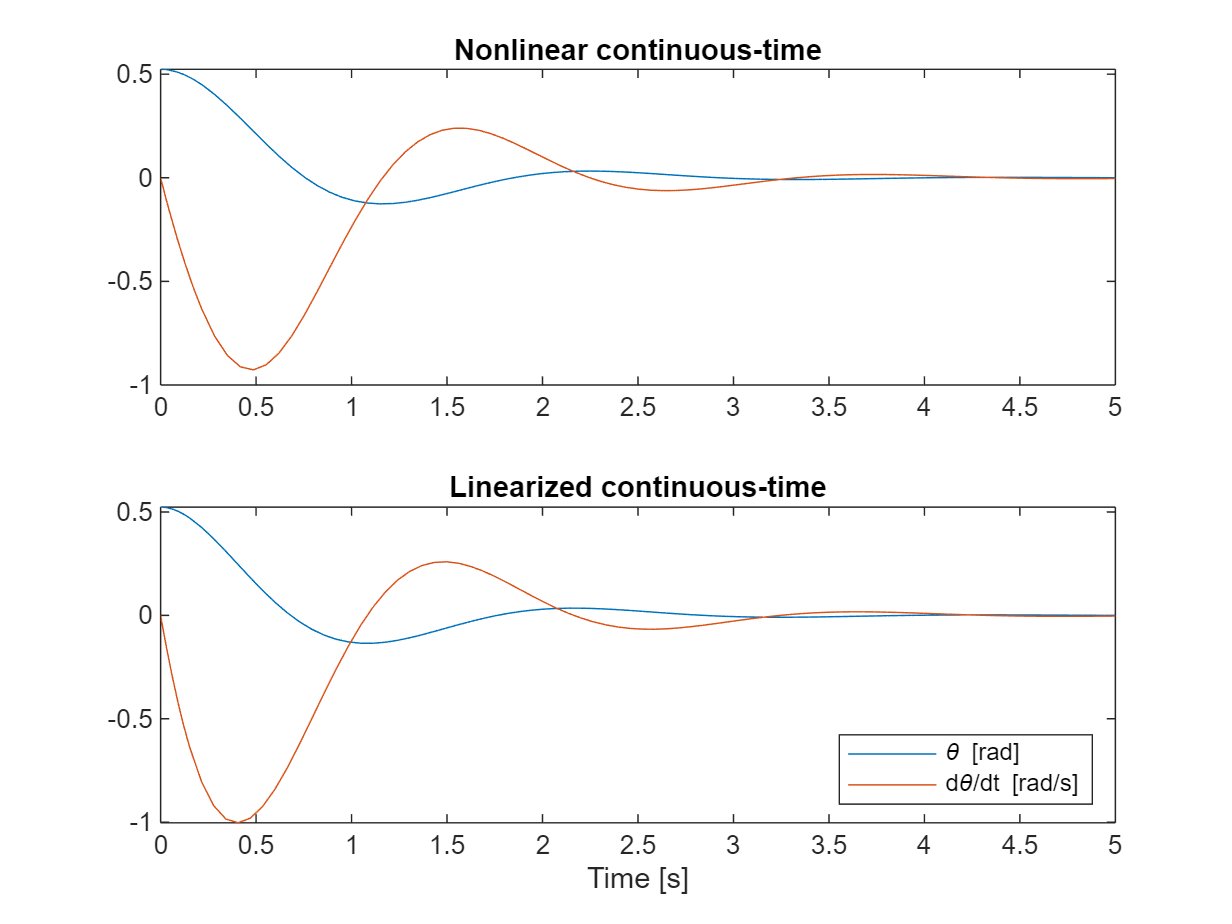

[tSimL,xSimL] = ode45(@(t,x) fxl + Ac*(x-xl'),[0, Tend],x0);

figure(2)
subplot(2,1,1)
plot(tSimNL,xSimNL)
title('Nonlinear continuous-time')

subplot(2,1,2)
plot(tSimL,xSimL)
title('Linearized continuous-time')
xlabel('Time [s]')
legend('\theta [rad]','d\theta/dt [rad/s]','Location','southeast')

Check for additional equilibrium points aside from origin.

c = k*a^2/(m*g*l)

c = 2

if c >= 1
    x_1_eq = acosd(1/c)
end

x_1_eq = 60.0000

## Exercise 3: Discretization

a) Euler discretization of nonlinear system

xEulerNL(1,:) = x0;
for i=1:fix(Tend/Ts)
    xEulerNL(i+1,:) = xEulerNL(i,:) + Ts*fx([],xEulerNL(i,:))';
end

b) Euler discretization of linear system

xEulerL(1,:) = x0;
for i=1:fix(Tend/Ts)
    xEulerL(i+1,:) = ((eye(2) + Ac*Ts)*xEulerL(i,:)' + Ts*(fxl - Ac*xl'))';
end

c) Exact discretization of linear system

[A,B] = c2d(Ac, [eye(2) -Ac], Ts);
xExactL(1,:) = x0;
for i=1:fix(Tend/Ts)
    xExactL(i+1,:) = (A*xExactL(i,:)' + B*[fxl; xl'])';
end

Plot results:

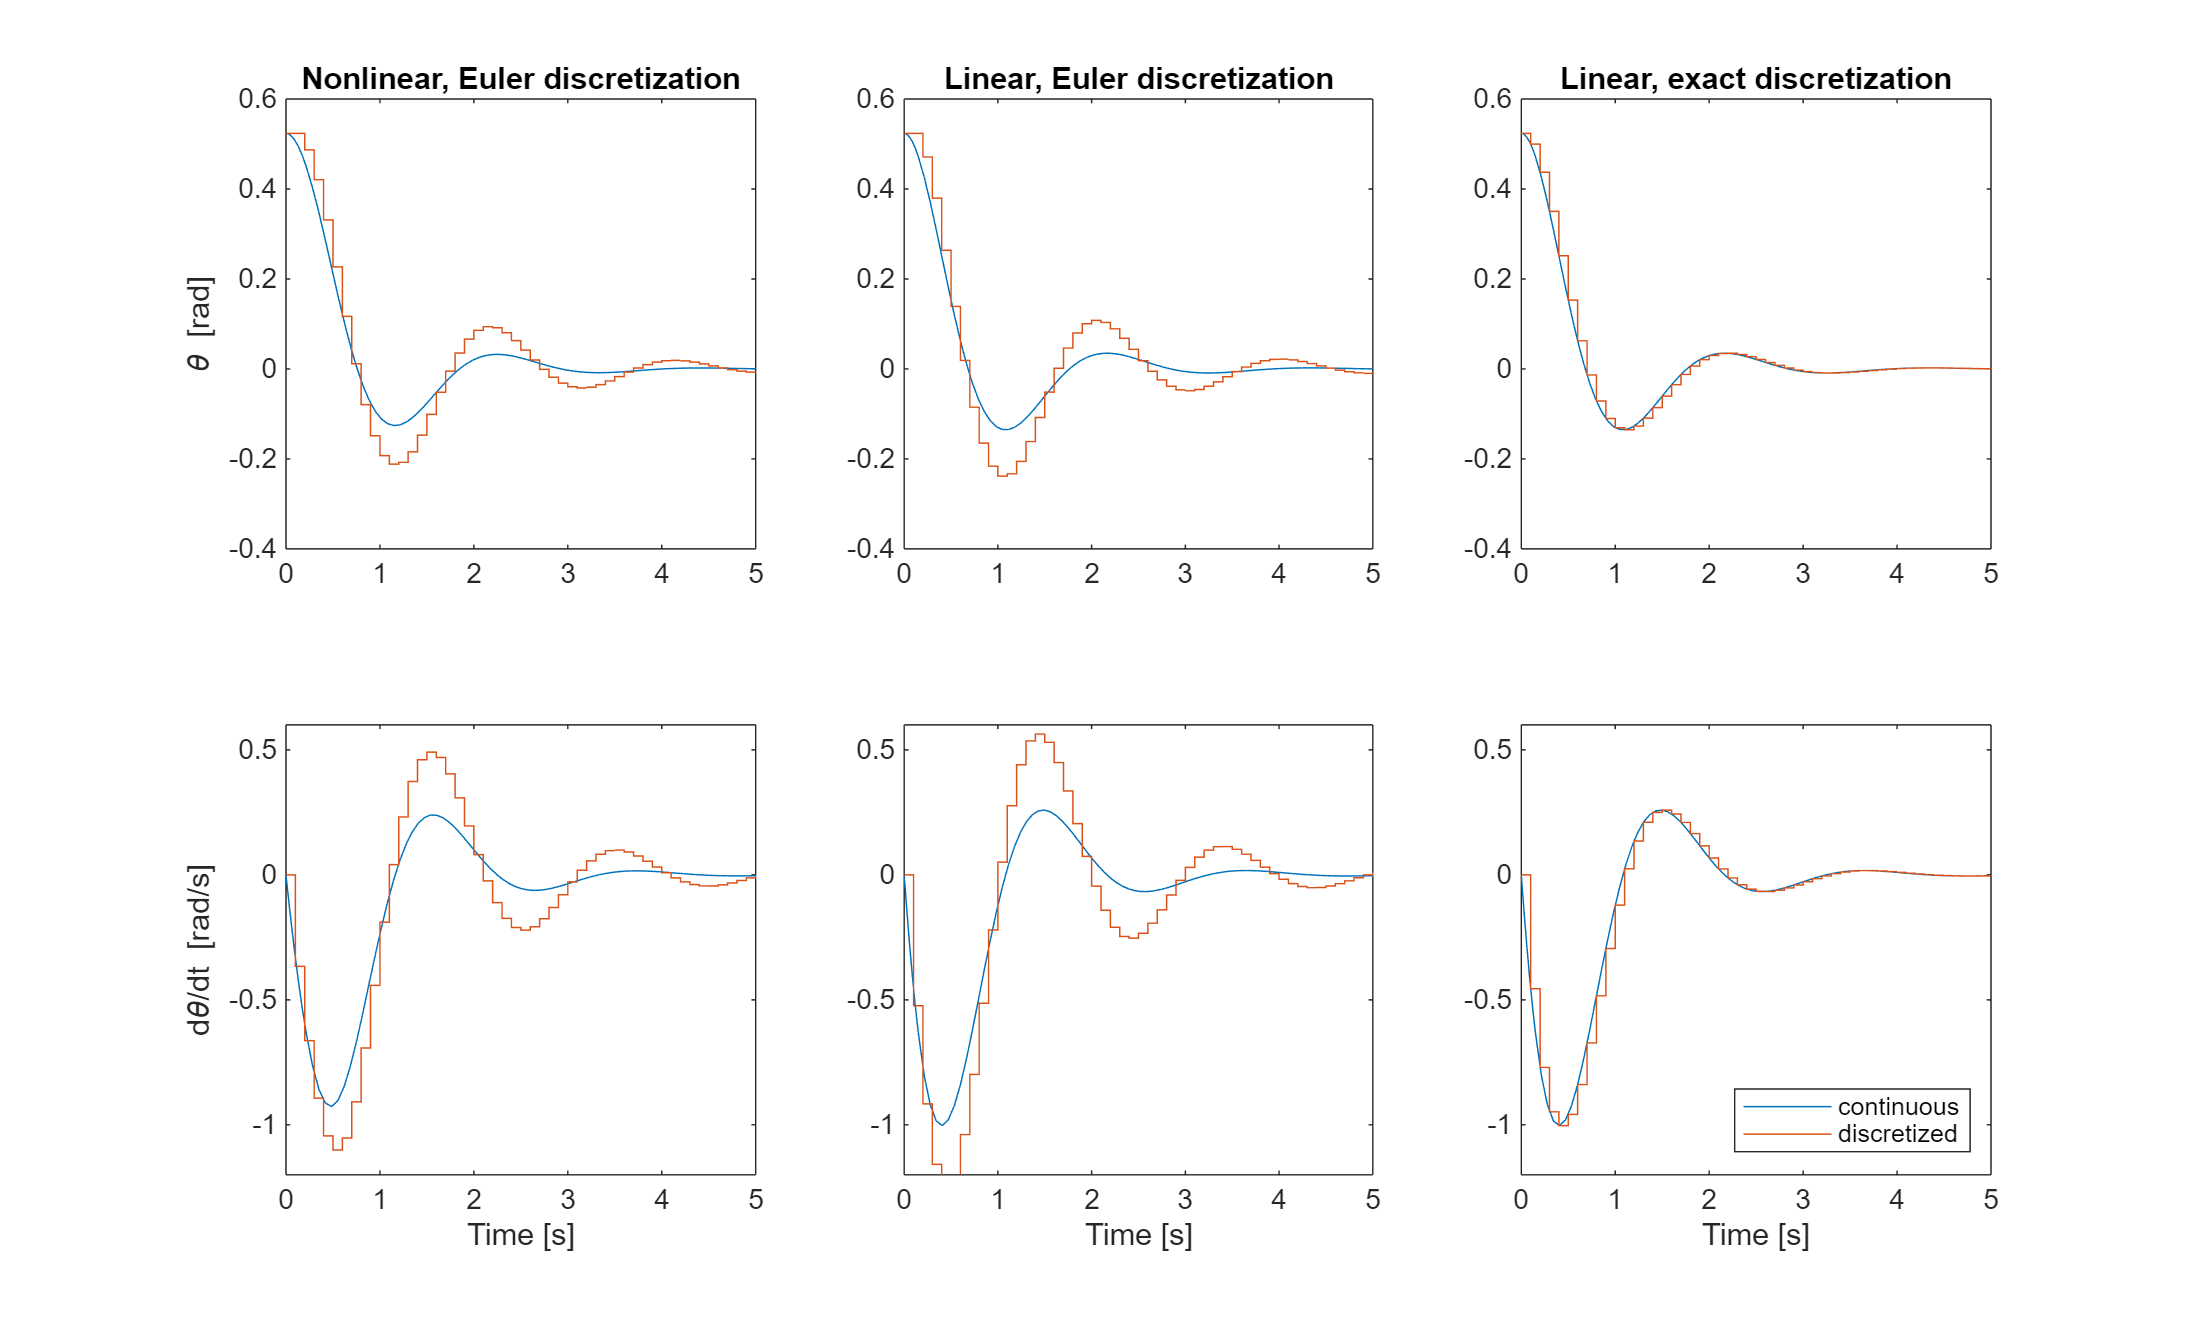

fig = figure(3);
fig.Position(3:4) = [1000, 600];

subplot(2,3,1)
plot(tSimNL,xSimNL(:,1))
hold on
stairs(0:Ts:Tend,xEulerNL(:,1))
xlim([0,Tend])
ylim([-0.4,0.6])
title('Nonlinear, Euler discretization')
ylabel('\theta [rad]')

subplot(2,3,2)
plot(tSimL,xSimL(:,1))
hold on
stairs(0:Ts:Tend,xEulerL(:,1))
xlim([0,Tend])
ylim([-0.4,0.6])
title('Linear, Euler discretization')

subplot(2,3,3)
plot(tSimL,xSimL(:,1))
hold on
stairs(0:Ts:Tend,xExactL(:,1))
xlim([0,Tend])
ylim([-0.4,0.6])
title('Linear, exact discretization')

subplot(2,3,4)
plot(tSimNL,xSimNL(:,2))
hold on
stairs(0:Ts:Tend,xEulerNL(:,2))
xlim([0,Tend])
ylim([-1.2,0.6])
ylabel('d\theta/dt [rad/s]')
xlabel('Time [s]')

subplot(2,3,5)
plot(tSimL,xSimL(:,2))
hold on
stairs(0:Ts:Tend,xEulerL(:,2))
xlim([0,Tend])
ylim([-1.2, 0.6])
xlabel('Time [s]')

subplot(2,3,6)
plot(tSimL,xSimL(:,2))
hold on
stairs(0:Ts:Tend,xExactL(:,2))
xlim([0,Tend])
ylim([-1.2,0.6])
xlabel('Time [s]')

legend('continuous','discretized','Location','southeast')